# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 곽명성**

**학번**** : 201911529**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/krSuoka/Disital-design.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

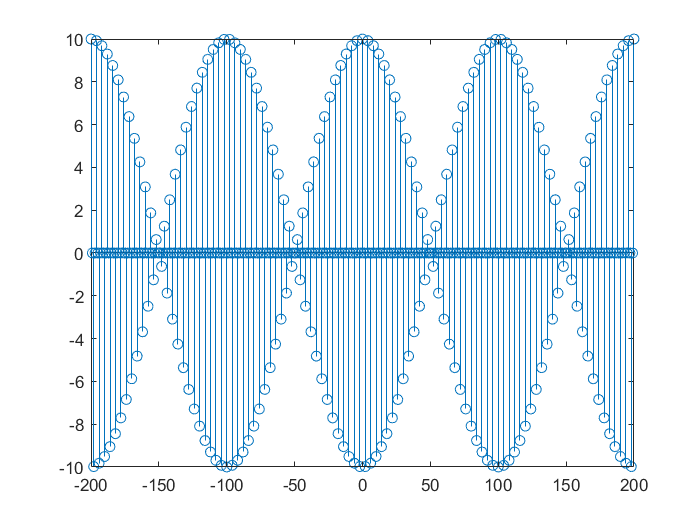

n=-200:1:200;
x=5*(cos(0.49*pi*n)+cos(0.51*pi*n));
figure()
stem(n,x);

2) 

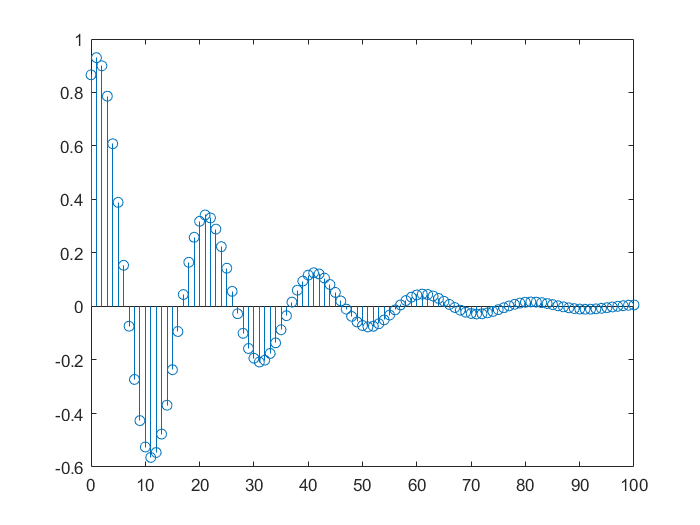

n=0:1:100;
x=exp(-0.05*n).*sin(0.1*pi*n+pi/3);
figure()
stem(n,x);

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

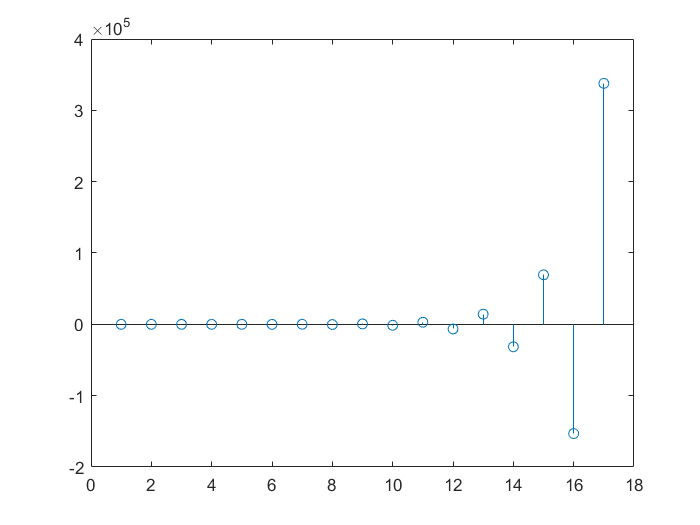

a=[1,2,0,1];
b=[1,-0.5,0.25];
[h,t]=impz(b,a);
n=0:100;
figure()
stem(h);

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

S=sum(abs(h));


3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

n=0:200;
x=(5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n));
h=filter(a,b,x);


3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

n=0:50

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


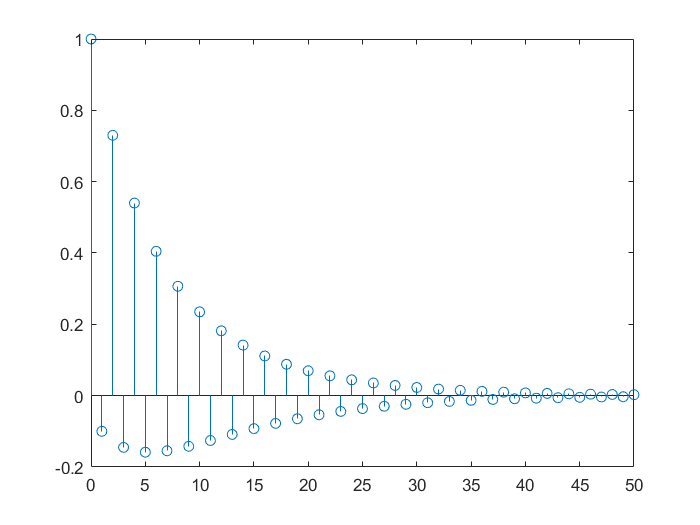

x=(0.8).^n.*(n>=0); h=(-0.9).^n.*(n>=0);
y=conv(x,h);
figure();
stem(n,y(1:length(n)))

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

n=0:25

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


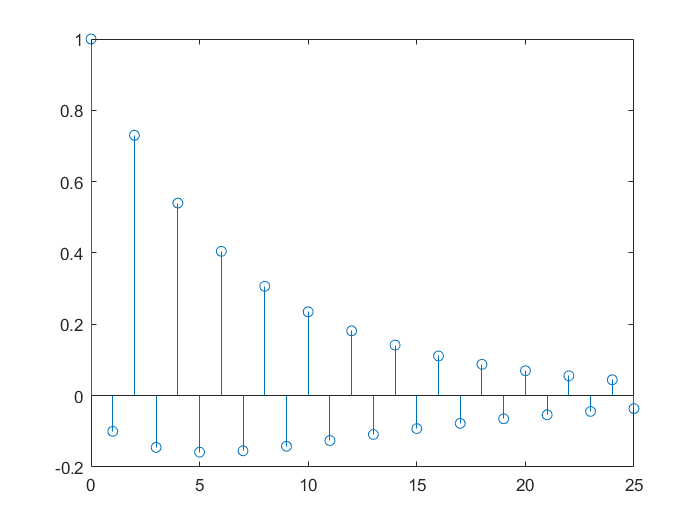

x=(0.8).^n.*(n>=0); h=(-0.9).^n.*(n>=0);
y=conv(x,h);
figure();
stem(n,y(1:length(n)))

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

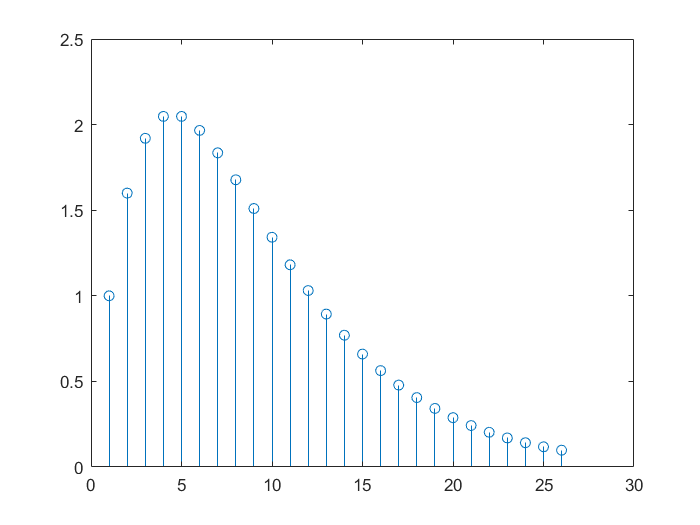

n=0:50;
a=(0.8).^n; b=1;
h=filter(a,b,x);
figure();
stem(h)

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

n=-pi:pi;
h=(0.9).^abs(n);
H=freqz(h);
[mag,phase,wout] = bode(H);

'bode'에 다음 중 하나가 필요함: 
  Control System Toolbox
  System Identification Toolbox

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

n=-pi:pi;
h=((0.5).^n+(0.4).^n).*(n>=0);
H=freqz(h);
[mag,phase,wout] = bode(H);

5. (P3.17) 

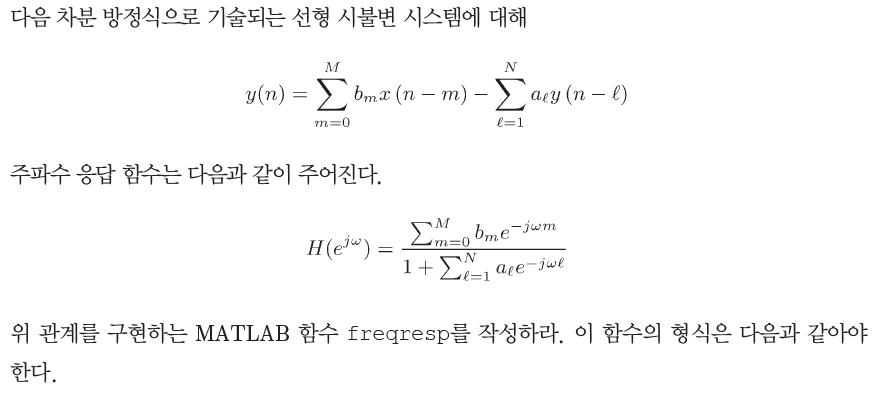

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

end

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

a=[1,0,-2];
b=[1,-0,95,0,9025];
[h,t]=frequz(b,a);
[mag,phase,wout] = bode(H);

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$